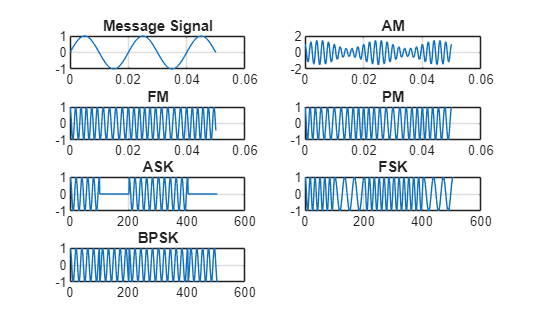

clc; clear; close all;

%% PARAMETERS
Am = 1;          % Message amplitude
fm = 50;         % Message frequency (Hz)

Ac = 1;          % Carrier amplitude
fc = 500;        % Carrier frequency (Hz)

fs = 10000;      % Sampling frequency
T  = 0.05;       % Total time
t  = 0:1/fs:T;

%% MESSAGE SIGNAL
m = Am * sin(2*pi*fm*t);

%% ================= ANALOG MODULATION =================

% --- AM ---
ka = 0.5;   % AM modulation index
s_am = Ac * (1 + ka*m) .* cos(2*pi*fc*t);

% --- FM ---
kf = 50;                          % Frequency sensitivity
int_m = cumsum(m) / fs;           % Integral of message
s_fm = Ac * cos(2*pi*fc*t + 2*pi*kf*int_m);

% --- PM ---
kp = pi/2;                        % Phase sensitivity
s_pm = Ac * cos(2*pi*fc*t + kp*m);

%% ================= DIGITAL MODULATION =================

data = [1 0 1 1 0];   % Binary data
Tb = 0.01;            % Bit duration

% --- ASK ---
s_ask = [];
for bit = data
    tt = 0:1/fs:Tb;
    if bit == 1
        sig = Ac*cos(2*pi*fc*tt);
    else
        sig = zeros(size(tt));
    end
    s_ask = [s_ask sig];
end

% --- FSK ---
f1 = 600; f0 = 300;
s_fsk = [];
for bit = data
    tt = 0:1/fs:Tb;
    if bit == 1
        sig = Ac*cos(2*pi*f1*tt);
    else
        sig = Ac*cos(2*pi*f0*tt);
    end
    s_fsk = [s_fsk sig];
end

% --- BPSK ---
s_bpsk = [];
for bit = data
    tt = 0:1/fs:Tb;
    if bit == 1
        sig = Ac*cos(2*pi*fc*tt);
    else
        sig = Ac*cos(2*pi*fc*tt + pi);
    end
    s_bpsk = [s_bpsk sig];
end

%% ================= PLOTS =================
figure;

subplot(4,2,1), plot(t,m), title('Message Signal'), grid on
subplot(4,2,2), plot(t,s_am), title('AM'), grid on

subplot(4,2,3), plot(t,s_fm), title('FM'), grid on
subplot(4,2,4), plot(t,s_pm), title('PM'), grid on

subplot(4,2,5), plot(s_ask), title('ASK'), grid on
subplot(4,2,6), plot(s_fsk), title('FSK'), grid on

subplot(4,2,7), plot(s_bpsk), title('BPSK'), grid on